# Discrete time systems

## Exercise 1

Consider the system


$$\dot{x} =\left\lbrack \begin{array}{cc}
-5 & -4\\
1 & -5
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
2\\
3
\end{array}\right\rbrack u$$



$$y=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack x$$


### 1. Design a feedback control law that places the poles at $\left\lbrace -1,-2\right\rbrace$

First we have $A,B\;\mathrm{and}\;y$

A = [-5 -4;
     1 -5];
B = [2;
     3];
C = [1 0];

Note the poles:

p = [-1 -2];

We place the poles in the system to find the gain matrix $K$

K = -place(A,B,p)

K =     0.9500    1.7000


### 2. Design a full order observer for the system placing the observer poles at $\left\lbrace -6,-9\right\rbrace \ldotp$

An observer takes in the input $u$ and the output of the plant $y$ of the system, and it can then estimate $\hat{x}$ which is estimates of the states.


$$\dot{\hat{x} } =A\;\hat{x} +B\;u+L\left(y-\hat{y} \right)$$



$$\hat{y} =C\;\hat{x}$$


We have the error 


$$e=\left(A-\mathrm{LC}\right)e$$


Where $e\left(k\right)=x-\hat{x}$

op = [-6, -9];

We place the observer poles: Note that since $\mathrm{LC}$ is subtracted, we do not want the $-$ before the place function. Since i need to transpose the $A-\mathrm{LC}$ to get it to $A^* -C^* L^*$, where $\mathrm{place}\left(A^* ,C^* \right)$ gives $L^*$, thus i need to retranspose it to get $L$

L = place(A',C',op)'

L =     5.0000
   -0.0000


This also fits the rule of thumb that the eigenvalues of $L$ should be 5 to 10 times higher than the eigenvalues of K.

In order to design a full order observer, which entails that i should find the equations for the observer, 

Note that we have the standard system $\dot{x} =\mathrm{Ax}+\mathrm{Bu}$

Where $u=K\;x$

Thus 


$$\dot{x} =\mathrm{Ax}+\mathrm{BK}\;x$$


We also know that the $\dot{e} =x-\hat{x}$ 


$$\begin{array}{l}
\dot{x} =\mathrm{Ax}+B\;K-B\;K\;e\\
\;\;\;=\left(A+B\;K\right)x-B\;K\;e
\end{array}$$


and collecting into matrix form


$$\dot{\left\lbrack \begin{array}{c}
x\\
e
\end{array}\right\rbrack } =\left\lbrack \begin{array}{cc}
A+B\;K & -B\;K\\
0 & A-L\;C
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
e
\end{array}\right\rbrack$$


### 3. Simulate the system using an ode function in MATLAB. Use ode45() in MATLAB.

First we combine the entire system into a matrix $\bar{A}$

A_bar = [A+B*K -B*K;
 [0 0;
 0 0] A-L*C];

Let $z=\left\lbrack \begin{array}{c}
x\\
e
\end{array}\right\rbrack$

And we need initial conditions $z_0 =\left\lbrack \begin{array}{c}
x_0 \\
e_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 001 & 0\ldotp 001\\
0 & 0
\end{array}\right\rbrack$ in 

z0 = [0.001 0.001;
      0     0];

Then using ode45

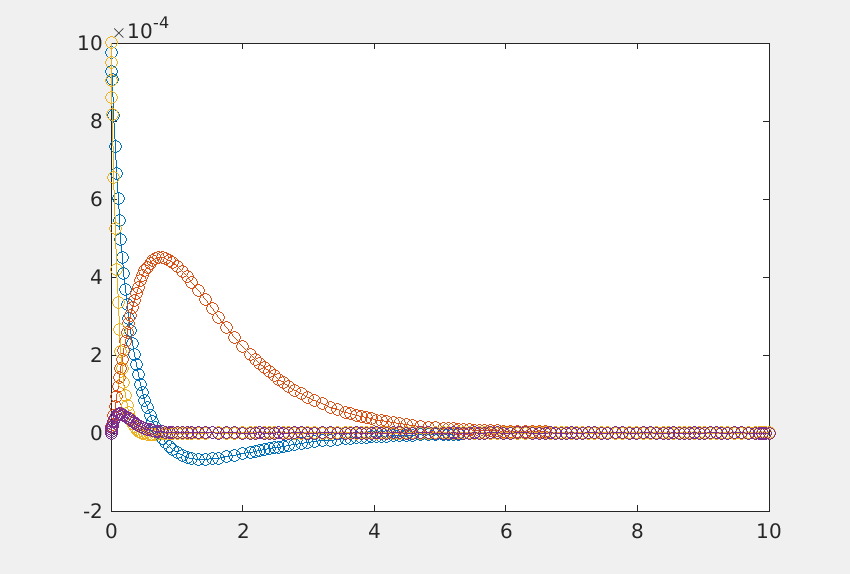

ode45(@(t,z) A_bar*z,[0,10],z0);

### 4. Introduce a reference and design an integral control law for the system and simulate its behavior.

An estimator-controller system is on the form


$$\dot{\hat{x} } =A\hat{x} +B\;u+L\left(y-\hat{y} \right)$$



$$\dot{x_I } =y-r$$



$$u=K\;\hat{x} +K_I +N\;r$$


Where $r$ is the reference to track, and now we have $\bar{K} =\left\lbrack \begin{array}{cc}
K & K_I 
\end{array}\right\rbrack$

This system takes the form


$$\dot{\left\lbrack \begin{array}{c}
x\\
x_I \\
e
\end{array}\right\rbrack } =\left\lbrack \begin{array}{ccc}
A+B\;K & B\;K_I  & -B\;K\\
C & 0 & 0\\
0 & 0 & A-L\;C
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
x_I \\
e
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\;N\\
-I\\
0
\end{array}\right\rbrack r$$


Thus we need to design a control law which makes

Where $B\;N\;r=B\;N_u \;r-B\;K\;N_x \;r$ and $N=\left\lbrack \begin{array}{c}
N_x \\
N_u 
\end{array}\right\rbrack$

And for a steady state input pair $\left(x^{\prime } ,u^{\prime } \right)\to \left\lbrack \begin{array}{c}
x^{\prime } \\
u^{\prime } 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cc}
A & B\\
C & 0
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r=\left\lbrack \begin{array}{c}
N_x \\
N_u 
\end{array}\right\rbrack r$

Thus the control law solving the tracking problem is 


$$u=K\left(x-N_x \;r\right)+N_u \;r$$


NxNu = inv([A B; C 0])*transpose([0 0 1])

NxNu =     1.0000
   -8.5000
  -14.5000



% extract Nx and Nu
% Determine the size of the state vector x0 and the number of control inputs
size_x0 = size(A, 1);
num_inputs = size(B, 2);

% Extract the appropriate parts of NxNu to get Nx and Nu
Nx = NxNu(1:size_x0, 1:num_inputs);
Nu = NxNu(size_x0+1:end, :);
N=Nu-K*Nx;

In order to find the gain matrix $\bar{K} =\left\lbrack \begin{array}{cc}
K & K_I 
\end{array}\right\rbrack$

I just need to use place on 


$$\dot{\left\lbrack \begin{array}{c}
x\\
x_I 
\end{array}\right\rbrack } =\left\lbrack \begin{array}{cc}
A & 0\\
C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
x_I 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack u-\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r$$


Where the new system is $\bar{A} x+\bar{B} u-G\;r$

and with 3 poles in the with negative real part $p_i =\left\lbrack \begin{array}{cc}
p & -2
\end{array}\right\rbrack$ 

Kbar = -place([A [0;0]; C 0], [B; 0],[p -3])

Kbar =     0.8000    0.8000    3.0000


So now that i have N i can compute the new $A$ matrix, call it $A_{\mathrm{rI}}$ for $A$ reference integral.


$$\left\lbrack \begin{array}{ccc}
A+B\;K & B\;K_I  & -B\;K\\
C & 0 & 0\\
0 & 0 & A-L\;C
\end{array}\right\rbrack$$


Ari = [A+B*Kbar(1:2) B*Kbar(3) -B*Kbar(1:2);
       C     0         [0 0];
       [0 0;
        0 0]     [0;0]         A-L*C]

Ari =    -3.4000   -2.4000    6.0000   -1.6000   -1.6000
    3.4000   -2.6000    9.0000   -2.4000   -2.4000
    1.0000         0         0         0         0
         0         0         0  -10.0000   -4.0000
         0         0         0    1.0000   -5.0000


Bri = [B*N;
       -eye(size(C,1))
       [0;0]];

Now lets introduce the reference:

r = 100;

So now we have the system:


$$\dot{\left\lbrack \begin{array}{c}
x\\
x_I \\
e
\end{array}\right\rbrack } =\left\lbrack \begin{array}{ccc}
A+B\;K & B\;K_I  & -B\;K\\
C & 0 & 0\\
0 & 0 & A-L\;C
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
x_I \\
e
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\;N\\
-I\\
0
\end{array}\right\rbrack r$$



$$\dot{z_{\mathrm{rI}} } =A_{\mathrm{rI}} \;z_{\mathrm{rI}} +B_{\mathrm{rI}} \;r$$


zri0 = [0.001;
        0;
        0; 
        0;
        0]

zri0 = 1.0e-03 *

    1.0000
         0
         0
         0
         0


[t,z] = ode45(@(t,zri) Ari*zri+Bri*r,[0,100],zri0);

We then plot only the state. 

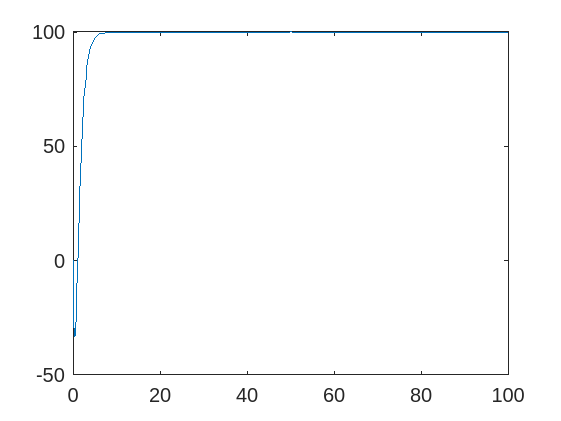

plot(t,C*z(:,1:2)')

Here it is evident that the state converges to the reference. 

### 5. Design reference feed-forward (Use the formulation illustrated in Fig. 8 in John's lecture note) and simulate it. 

We have the standard system


$$\dot{x} =\mathrm{Ax}+\mathrm{Bu}$$


And the observer system


$$\dot{\hat{x} } =A\;\hat{x} +B\;u+L\;\left(y-\hat{y} \right)$$


where $y=C\;x$

and


$$u=K\;\hat{x} +N\;r$$


If we insert $u$ and $y=\mathrm{Cx}$ into the other equations we have


$$\dot{x} =\mathrm{Ax}+\mathrm{BK}\;\hat{x} +\mathrm{BN}\;r$$



$$\dot{\hat{x} } =A\;\hat{x} +\mathrm{BK}\;\hat{x} +\mathrm{BN}\;r+\mathrm{LC}\;x-\mathrm{LC}\hat{x}$$


Then i can collect the terms into a new matrix A


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\hat{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & B\;K\\
\mathrm{LC} & A+B\;K-L\;C
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\;N\\
B\;N
\end{array}\right\rbrack r$$


Then i compute the new A

Aff = [A B*K;
       L*C A+B*K-L*C]

Aff =    -5.0000   -4.0000    1.9000    3.4000
    1.0000   -5.0000    2.8500    5.1000
    5.0000         0   -8.1000   -0.6000
   -0.0000         0    3.8500    0.1000


And the new N matrix

Nff = [B*N;
       B*N]

Nff =    -2.0000
   -3.0000
   -2.0000
   -3.0000


Then i set some initial conditions for this 

xbar0 = [2;
         4;
         7;
         3;];

And set the reference point.

r = 10;

And i simulate it. 

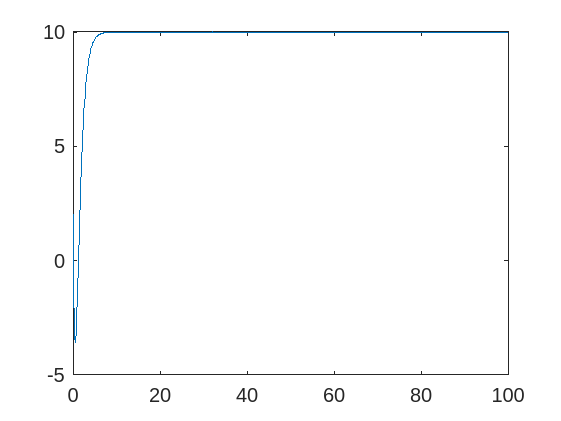

[t,xbar] = ode45(@(t,xbar) Aff*xbar+Nff*r,[0,100],xbar0);
plot(t,C*xbar(:,1:2)')